## 该代码为基于BP网络的语言识别

%% 清空环境变量
clc
clear

## 训练数据预测数据提取及归一化

%下载四类语音信号
load data1 c1
load data2 c2
load data3 c3
load data4 c4

%四个特征信号矩阵合成一个矩阵
data(1:500,:)=c1(1:500,:);
data(501:1000,:)=c2(1:500,:);
data(1001:1500,:)=c3(1:500,:);
data(1501:2000,:)=c4(1:500,:);

%从1到2000间随机排序
k=rand(1,2000);
[m,n]=sort(k);

%输入输出数据
input=data(:,2:25);
output1 =data(:,1);

%把输出从1维变成4维
output=zeros(2000,4);
for i=1:2000
    switch output1(i)
        case 1
            output(i,:)=[1 0 0 0];
        case 2
            output(i,:)=[0 1 0 0];
        case 3
            output(i,:)=[0 0 1 0];
        case 4
            output(i,:)=[0 0 0 1];
    end
end

%随机提取1500个样本为训练样本，500个样本为预测样本
input_train=input(n(1:1500),:)';
output_train=output(n(1:1500),:)';
input_test=input(n(1501:2000),:)';
output_test=output(n(1501:2000),:)';

%输入数据归一化
[inputn,inputps]=mapminmax(input_train);

## 网络结构初始化

innum=24;
midnum=25;
outnum=4;

%权值初始化
w1=rands(midnum,innum);
b1=rands(midnum,1);
w2=rands(midnum,outnum);
b2=rands(outnum,1);

w2_1=w2;w2_2=w2_1;
w1_1=w1;w1_2=w1_1;
b1_1=b1;b1_2=b1_1;
b2_1=b2;b2_2=b2_1;

%学习率
xite=0.1;
alfa=0.01;
loopNumber=10;
I=zeros(1,midnum);
Iout=zeros(1,midnum);
FI=zeros(1,midnum);
dw1=zeros(innum,midnum);
db1=zeros(1,midnum);


## 网络训练

E=zeros(1,loopNumber);
for ii=1:loopNumber
    E(ii)=0;
    for i=1:1:1500
       %% 网络预测输出 
        x=inputn(:,i);
        % 隐含层输出
        for j=1:1:midnum
            I(j)=inputn(:,i)'*w1(j,:)'+b1(j);
            Iout(j)=1/(1+exp(-I(j)));
        end
        % 输出层输出
        yn=w2'*Iout'+b2;
        
       %% 权值阀值修正
        %计算误差
        e=output_train(:,i)-yn;     
        E(ii)=E(ii)+sum(abs(e));
        
        %计算权值变化率
        dw2=e*Iout;
        db2=e';
        
        for j=1:1:midnum
            S=1/(1+exp(-I(j)));
            FI(j)=S*(1-S);
        end      
        for k=1:1:innum
            for j=1:1:midnum
                dw1(k,j)=FI(j)*x(k)*(e(1)*w2(j,1)+e(2)*w2(j,2)+e(3)*w2(j,3)+e(4)*w2(j,4));
                db1(j)=FI(j)*(e(1)*w2(j,1)+e(2)*w2(j,2)+e(3)*w2(j,3)+e(4)*w2(j,4));
            end
        end
           
        w1=w1_1+xite*dw1';
        b1=b1_1+xite*db1';
        w2=w2_1+xite*dw2';
        b2=b2_1+xite*db2';
        
        w1_2=w1_1;w1_1=w1;
        w2_2=w2_1;w2_1=w2;
        b1_2=b1_1;b1_1=b1;
        b2_2=b2_1;b2_1=b2;
    end
end
 

%% 语音特征信号分类
inputn_test=mapminmax('apply',input_test,inputps);
fore=zeros(4,500);
for ii=1:1
    for i=1:500%1500
        %隐含层输出
        for j=1:1:midnum
            I(j)=inputn_test(:,i)'*w1(j,:)'+b1(j);
            Iout(j)=1/(1+exp(-I(j)));
        end
        
        fore(:,i)=w2'*Iout'+b2;
    end
end


## 结果分析

%根据网络输出找出数据属于哪类
output_fore=zeros(1,500);
for i=1:500
    output_fore(i)=find(fore(:,i)==max(fore(:,i)));
end

%BP网络预测误差
error=output_fore-output1(n(1501:2000))';


### 预测语音种类和实际语音种类的分类图

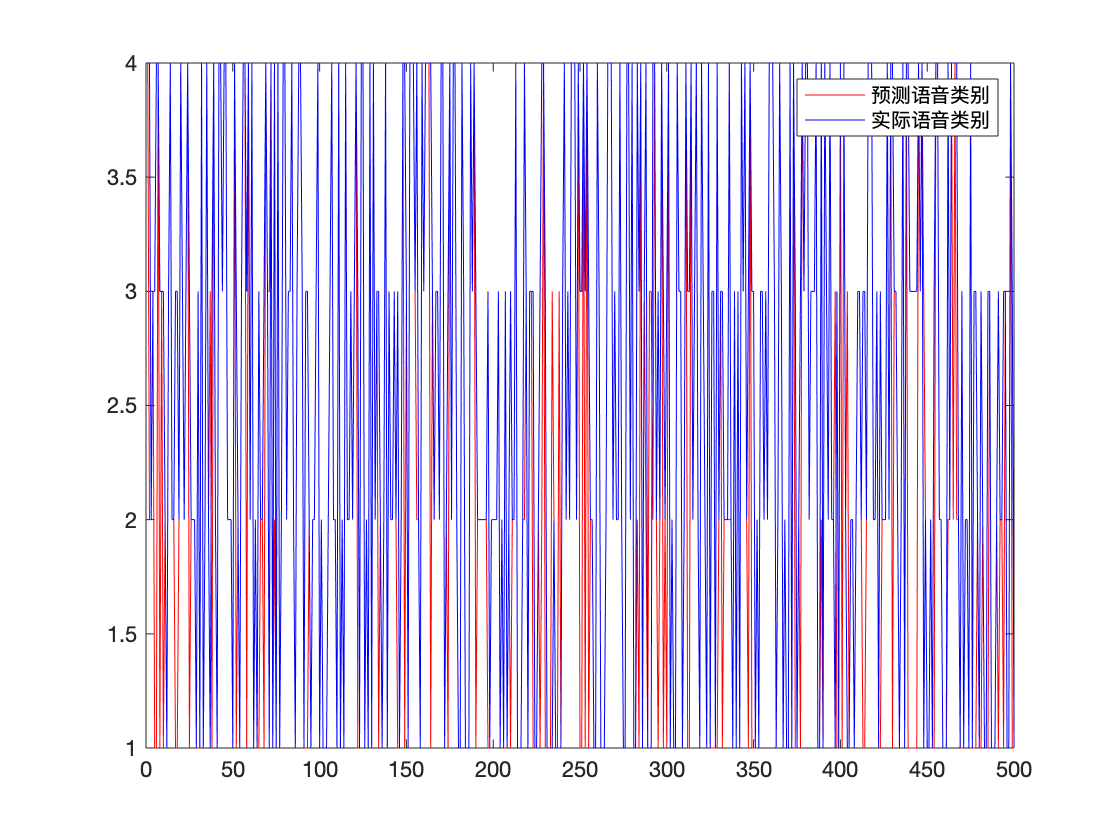

figure(1)
plot(output_fore,'r')
hold on
plot(output1(n(1501:2000))','b')
legend('预测语音类别','实际语音类别')

### 误差图

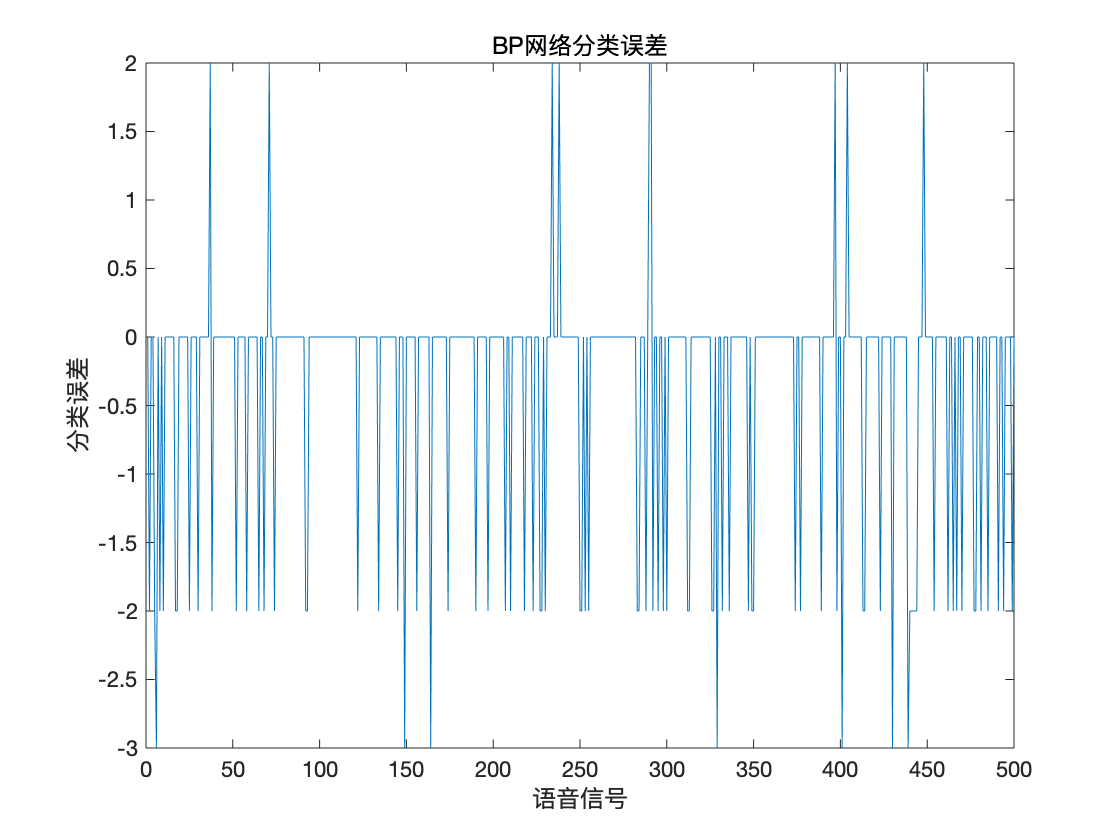

figure(2)
plot(error)
title('BP网络分类误差','fontsize',12)
xlabel('语音信号','fontsize',12)
ylabel('分类误差','fontsize',12)


%print -dtiff -r600 1-4

### 分类计算正确率

k=zeros(1,4);  
%找出判断错误的分类属于哪一类
for i=1:500
    if error(i)~=0
        [b,c]=max(output_test(:,i));
        switch c
            case 1 
                k(1)=k(1)+1;
            case 2 
                k(2)=k(2)+1;
            case 3 
                k(3)=k(3)+1;
            case 4 
                k(4)=k(4)+1;
        end
    end
end

%找出每类的个体和
kk=zeros(1,4);
for i=1:500
    [b,c]=max(output_test(:,i));
    switch c
        case 1
            kk(1)=kk(1)+1;
        case 2
            kk(2)=kk(2)+1;
        case 3
            kk(3)=kk(3)+1;
        case 4
            kk(4)=kk(4)+1;
    end
end
%正确率
rightridio=(kk-k)./kk;
disp(rightridio);

    0.9250    1.0000    0.5041    0.8462



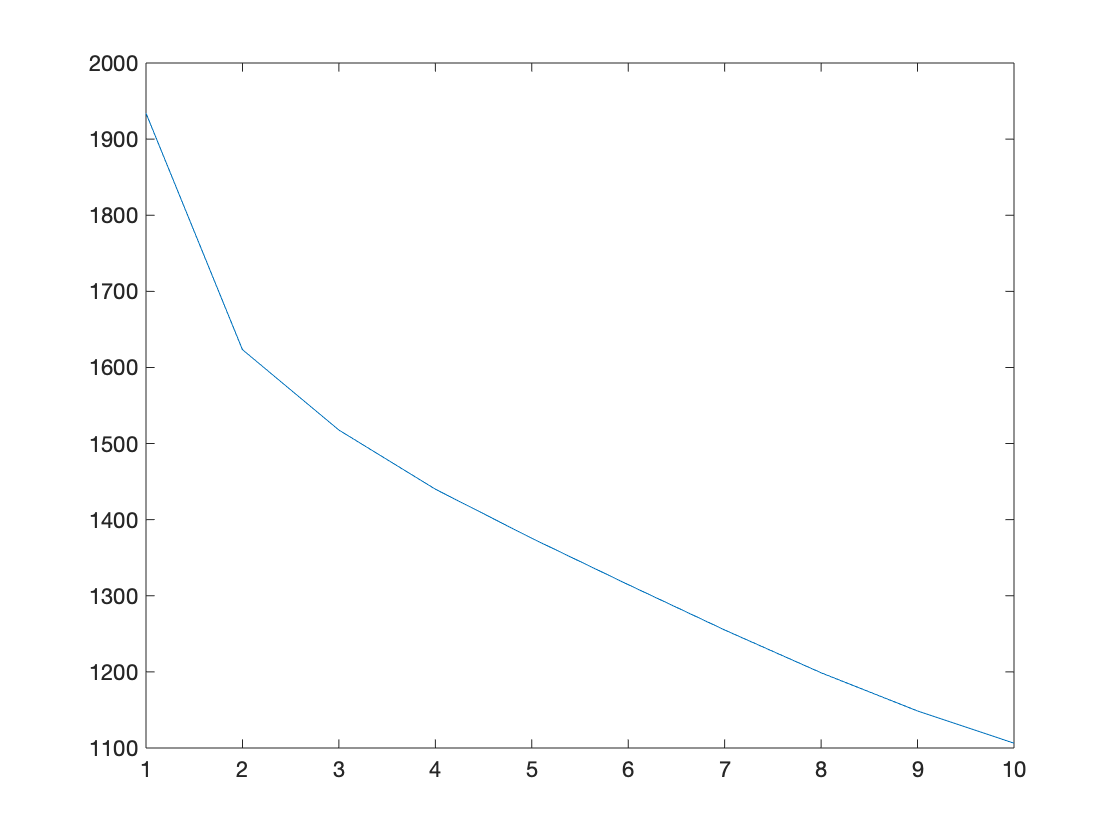

plot(E)